## Introduction

In this prelab, we will model a Conventional DC Motor and simulate it with a PWM input. Then we will apply a discrete PID controller to control the velocity, then the speed of the motor. 

## Motor Model

A conventional DC Motor can be modeled as part circuit part mechanical system, together termed as an electromechanical system. As shown in the following figure. 

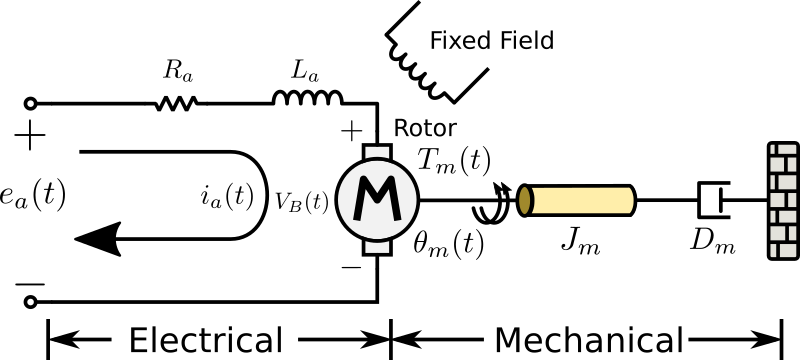

The motor can be modeled as a second order system with the transfer function

$\frac{\Omega \left(s\right)}{E_a \left(s\right)}=\frac{K_T }{{\textrm{JLs}}^2 +\left(\textrm{JR}+\textrm{bL}\right)s+\left(\textrm{bR}+K_T K_E \right)}$, where 

$J$is the motor load's inertia in $\textrm{Kg}\cdot m^2$

$b$ is the motor viscous friction constant in $N\cdot m\cdot s$

$K_E$ is the back EMF constant in $V/\left(\textrm{rad}\cdot s\;\right)$

$K_T$is the motor torque constant in $N\cdot \frac{m}{A}$

$R$ is the electrical resistance of the motor in $\textrm{Ohms}$

$L$ is the electrical inductance of the motor in $H$

Let's simulate the response of the motor to a step input

set(0, 'DefaultLineLineWidth', 2);

% Define Motor Parameters
J = 0.01;
D =0.05; 
Kt = 0.07; 
Ke = 0.04; 
R = 0.07;
L = 0.09;

J = 0.06; D =0.03; 
Kt = 0.07; Ke = 0.03; 
R = 0.07; L = 0.04;
s = tf("s");
Gp = Kt / (J * L * s^2 + (J*R + D*L)*s + (D*R + Kt*Ke))

Gp =
 
               0.07
  ------------------------------
  0.0024 s^2 + 0.0054 s + 0.0042
 
Continuous-time transfer function.



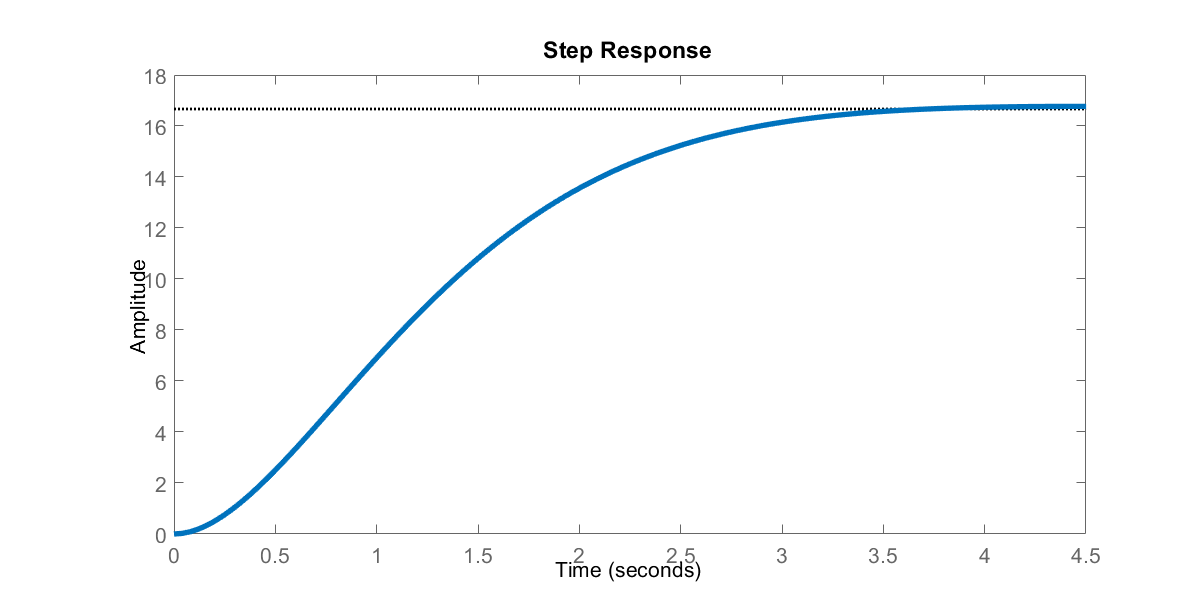

[x,t] = step(Gp);
fp = figure('Renderer', 'painters', 'Position', [10 10 800 400]);
stepplot(Gp); % Use this command to return plot handle to programmatically customize the plot.
prettyfigure(fp)

% TODO: add bode plot

Emulate a PWM Signal

Plot

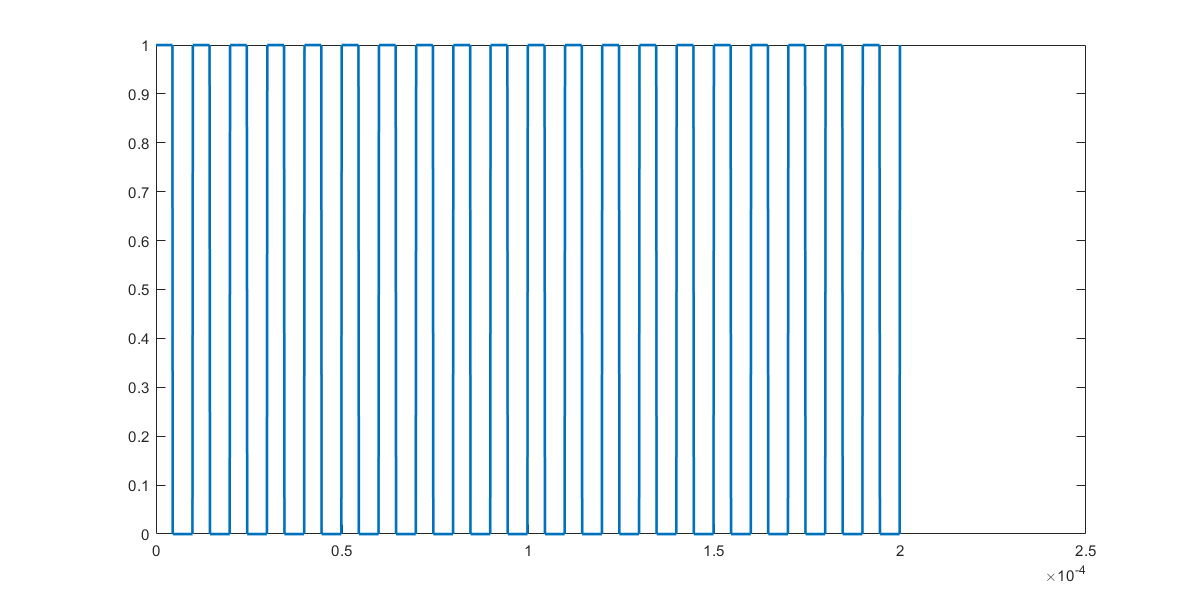

fpwm = figure('Position', [10 10 800 400]);
duty = 46;
frequency = 20000;
t_length = 4 / frequency;
[t, u] = pwm(duty, frequency, t_length);
plot(t,u);

%prettyfigure(fpwm);

Simulate the Motor Response to pwm signal. Note the effect of changing the pwm frequency on the response of the motor. 

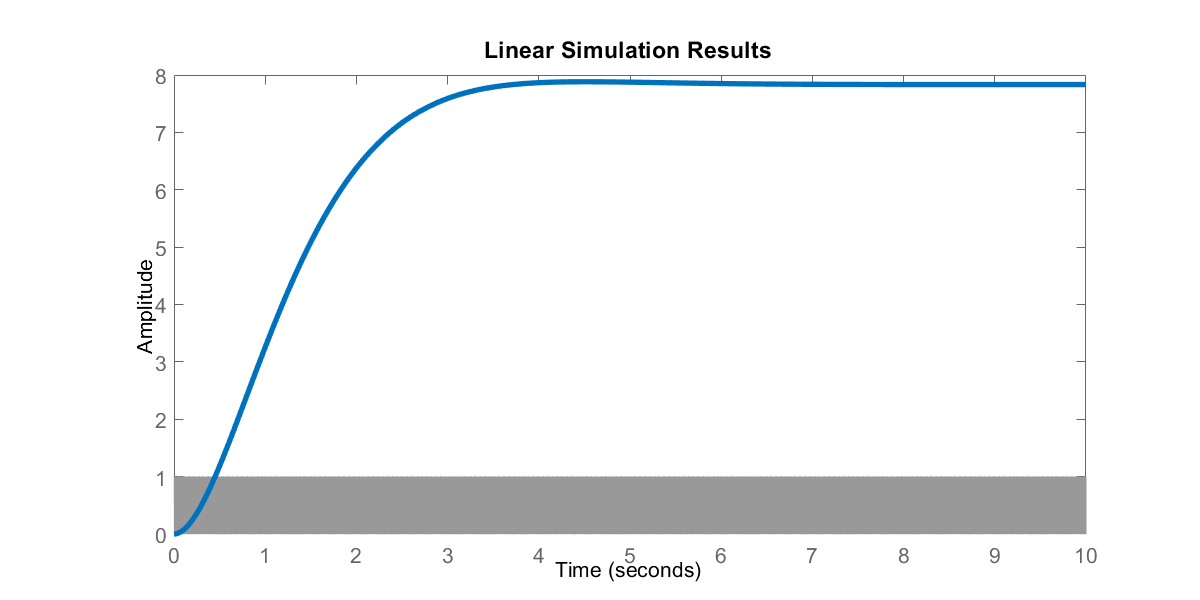

duty = 47;
frequency =  110;
t_length = 10;
fr_pwm = figure('Position', [10 10 800 400]);
[t, u] = pwm(duty, frequency, t_length);
lsim(Gp, u, t)
prettyfigure(fr_pwm);

Let's apply a PID controller to perform speed control of the motor

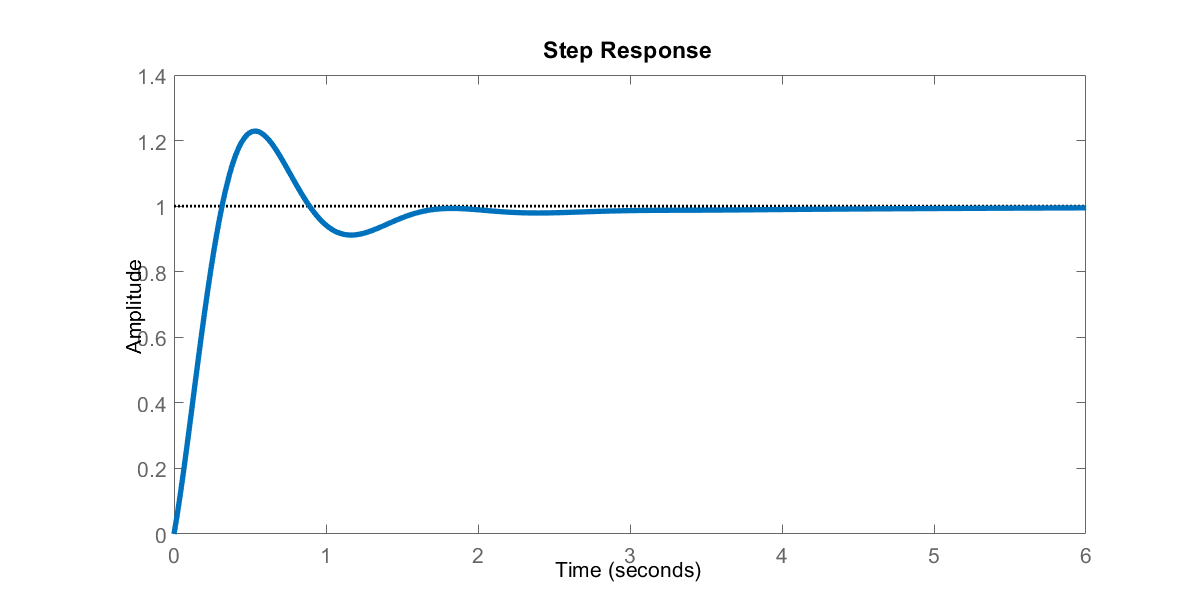

Kp =1;
Ki =0.34;
Kd =0.09;
s = tf('s');
Gc =( Kd*s^2 + Kp*s + Ki ) / s;
Gcl = feedback(Gc*Gp, 1); % Gc*Gp / (1+Gc*Gp)
fcl = figure('Renderer', 'painters', 'Position', [10 10 800 400]);
stepplot(Gcl); % Use this command to return plot handle to programmatically customize the plot.
prettyfigure(fcl);

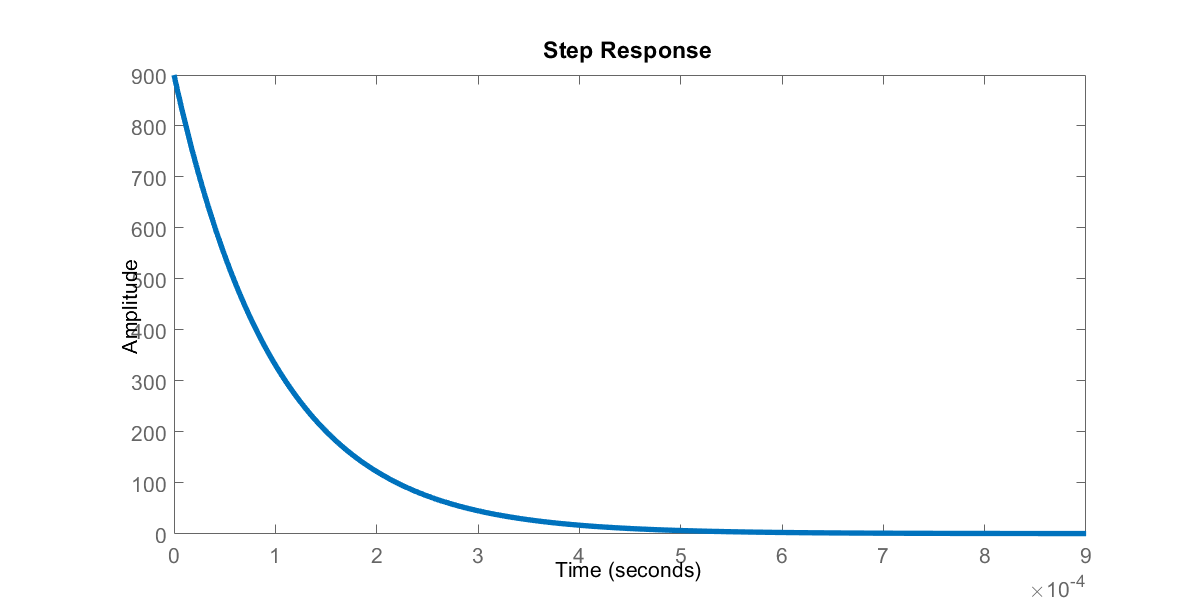

fu = figure('Position', [10 10 800 400]);
U = Gc*(1-Gcl);
step(U*10000/(s+10000));
prettyfigure(fu);

Simulate with numerical integration and apply the controller as a difference equation

### PID Controller in Discrete Form

The PID controller designed above is a continuous form PID controller. To translate the continuos form PID controller into discrete, we discretize it knowing the sampling time. We get

$u\left\lbrack k\right\rbrack =u\left\lbrack k-1\right\rbrack +a\cdot \;e\left\lbrack k\right\rbrack +b\cdot e\left\lbrack k-1\right\rbrack +c\cdot e\left\lbrack k-2\right\rbrack$, where $a=\left(K_{p\;} +K_{i\;} \frac{T_s }{2}+\frac{K_d }{T_s }\right)$, $b=\left(-K_{p\;} +K_{i\;} \frac{T_s }{2}-\frac{2K_d }{T_s }\right)$, $c=\frac{K_d }{T_s }$

And $K_p$, $K_i$, $K_d$ are the propprtional, integral and derivative gains of the continuos form PID controller and $T_s$ is the sampling time.

### Motor Simulation using Numerical Integration

To simulate the motor using basic numerical integration, we first have to repesent the model of the system in the time domain $\dot{x} =f\left(x,u,t\right)$

Kp =0.5; Ki =0.05; Kd =0;
% x = [omega i], u = Ea
J = 0.06; D =0.03; 
Kt = 0.07; Ke = 0.03; 
R = 0.07; L = 0.04;
Ts = 0.01;
a = (Kp + Ki * Ts / 2 + Kd / Ts); b = (-Kp + Ki * Ts / 2 - 2 * Kd / Ts); c = Kd / Ts

c = 0


dxdt = @(t,x,E)[ 
    x(2);
    1/(J*L) * (Kt*E - (D*R + Kt*Ke)*x(1) - (J*R + D*L)*x(2));
    (E - Ke*x(1)-R*x(3))/L
    ]

dxdt = function_handle with value:
    @(t,x,E)[x(2);1/(J*L)*(Kt*E-(D*R+Kt*Ke)*x(1)-(J*R+D*L)*x(2));(E-Ke*x(1)-R*x(3))/L]


    
t = 0:Ts:5;
x_sim = zeros(3,length(t)); % Empty 2xn array
u = zeros(1,length(t)); % Empty 1xn vector
e = u; % Empty 1xn vector
r = 5;
for ix = 1:length(t)

    % Compute the error
    e(1, ix) = r -  x_sim(1, ix);
    % Calculate the next input value 
    
    if (ix > 2)
        u(1,ix) = u(1,ix-1) + a * e(1,ix) + b * e(1,ix-1) + c * e(1,ix-2);    
    elseif (ix == 2)
        u(1,ix) = u(1,ix-1) + a * e(1,ix) + b * e(1,ix-1) + 0;
    elseif (ix == 1)
        u(1,ix) =  0 + a * e(1,ix) + 0 + 0;
    end
    
    xdot = dxdt(t(ix), x_sim(:,ix), 1); % Grab the derivative vector
    
    if(ix < length(t) )
        x_sim(:, ix+1) = x_sim(:, ix) + xdot * Ts;      
    end
end


Plot the simulated parameters

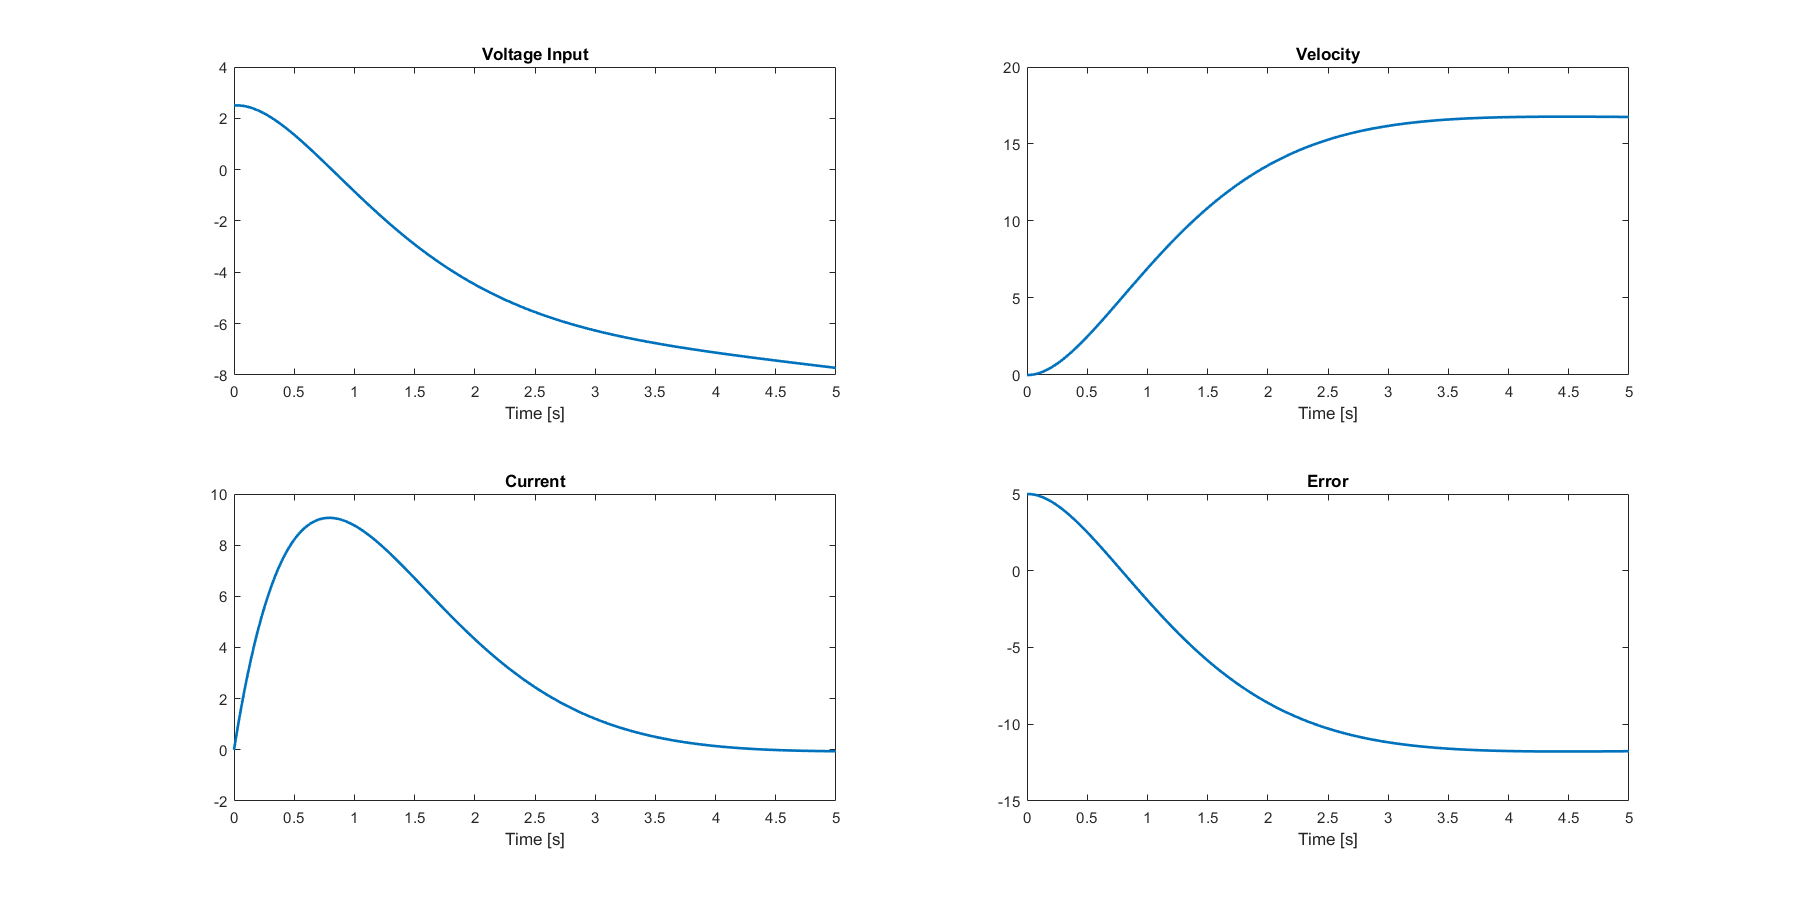

fsim = figure('Position', [10 10 1200 600]);
subplot(2,2,1); 
plot(t, u(1,:)); title('Voltage Input'); xlabel('Time [s]');
subplot(2,2,2); 
plot(t, x_sim(1,:)); title('Velocity'); xlabel('Time [s]');
subplot(2,2,3); 
plot(t, x_sim(2,:)); title('Current'); xlabel('Time [s]');
subplot(2,2,4); 
plot(t, e(1,:)); title('Error'); xlabel('Time [s]');